# Coupled Epidemic and Opinion Dynamics Simulation

clc;
clear all;
close all;

## First Section: Parameter Initialization

n = 10; % Number of communities
t_max = 300; % Maximum time steps
delta_min = 1.9; % Minimum healing rate
beta_min = 0.8; % Minimum infection rate
delta = delta_min + 0.5 * rand(n, 1); % Max healing rates (randomized)
beta = beta_min + 0.5 * rand(n, 1); % Max infection rates (randomized)

## 

## Second Section: Initial States

x = rand(n, 1); % Initial infection levels
o = rand(n, 1) - 0.5; % Initial opinions in range [-0.5, 0.5]

## Third Section: Graph Structures

###     Epidemic adjacency matrix

A = rand(n); % Random adjacency weights
A(A < 0.7) = 0; % Threshold to remove weak connections
A = triu(A, 1); % Make upper triangular (for undirected graph)
A = A + A'; % Symmetrize to create an undirected graph

###     

###     Opinion adjacency matrix

A_opinion = rand(n) - 0.5; % Random signed opinion interactions
A_opinion(abs(A_opinion) < 0.8) = 0; % Threshold to remove weak interactions
A_opinion_base = abs(A_opinion); % Base influence matrix (absolute values)

## 

## Fourth Section: Stubborn Nodes

stubborn_nodes = [1, 6, 9]; % Nodes with fixed opinions
o_stubborn = 0.5 * ones(length(stubborn_nodes), 1); % Fixed opinions for stubborn nodes

## Fifth Section: History and Convergence Tracking

R_o_history = zeros(1, t_max); % History of reproduction numbers
x_history = zeros(n, t_max); % History of infection levels
o_history = zeros(n, t_max); % History of opinions
converged = false; % Convergence flag

## Sixth Section: Simulation Loop

for t = 1:t_max
    % Initialize change rates
    dx = zeros(n, 1); 
    do = zeros(n, 1);

    % Update infection dynamics
    for i = 1:n
        % Effective healing rate
        delta_effective = delta_min + (delta(i) - delta_min) * (o(i) + 0.5);
        healing_effect = -delta_effective * x(i);

        % Effective infection rate from neighbors
        infection_effect = 0;
        for j = 1:n
            if A(i, j) > 0 % If a connection exists
                beta_effective = beta(j) - (beta(j) - beta_min) * (o(i) + 0.5);
                infection_effect = infection_effect + beta_effective * x(j);
            end
        end
        infection_effect = (1 - x(i)) * infection_effect;

        % Total infection change
        dx(i) = healing_effect + infection_effect;
    end

    % Update opinion dynamics
    sign_matrix = diag(sign(o)); % Determine cooperative/antagonistic relationships
    A_opinion_dynamic = sign_matrix * A_opinion_base * sign_matrix; % Adjust opinion adjacency matrix

    % Compute opinion change
    o_effective = o + 0.5; % Shift opinions into [0, 1]
    do = (x - o_effective) + A_opinion_dynamic * (sign(A_opinion) .* o - o);

    % Ensure `do` is a column vector
    do = sum(do, 2); 

    % Enforce stubborn node opinions
    do(stubborn_nodes) = 0; 
    o(stubborn_nodes) = o_stubborn;

    % Update states
    x = x + dx * 0.01; % Scaled infection update
    x = max(0, min(1, x)); % Clamp infection levels to [0, 1]

    o = o + do * 0.01; % Scaled opinion update
    o = max(-0.5, min(0.5, o)); % Clamp opinions to [-0.5, 0.5]

    % Compute opinion-dependent reproduction number
    D_effective = diag(delta_min + (delta - delta_min) .* (o + 0.5)); % Effective healing matrix
    B_effective = diag(beta) * A; % Effective infection matrix

    % Ensure both matrices are square
    assert(size(D_effective, 1) == size(D_effective, 2), 'D_effective is not square')
    assert(size(B_effective, 1) == size(B_effective, 2), 'B_effective is not square')

    % Compute R_o
    R_o = max(real(eig(D_effective \ B_effective))); % Spectral radius for R_o
    R_o_history(t) = R_o; 

    % Save history
    x_history(:, t) = x; 
    o_history(:, t) = o;

    % Check for convergence
    if t > 1
        dx_norm = norm(x_history(:, t) - x_history(:, t-1));
        do_norm = norm(o_history(:, t) - o_history(:, t-1));
        if dx_norm < 1e-5 && do_norm < 1e-5 && ~converged
            fprintf('System converged at step %d\n', t);
            converged = true;
        end
    end
end

## Final State Classification

if all(x < 1e-5) % Infection has died out
    if all(abs(o - mean(o)) < 1e-2) 
        fprintf('Consensus-Healthy State.\n');
    else
        fprintf('Dissensus-Healthy State.\n');
    end
else % Infection persists
    if all(abs(o - mean(o)) < 1e-2) 
        fprintf('Consensus-Endemic State.\n');
    else
        fprintf('Dissensus-Endemic State.\n');
    end
end

Dissensus-Endemic State.


## 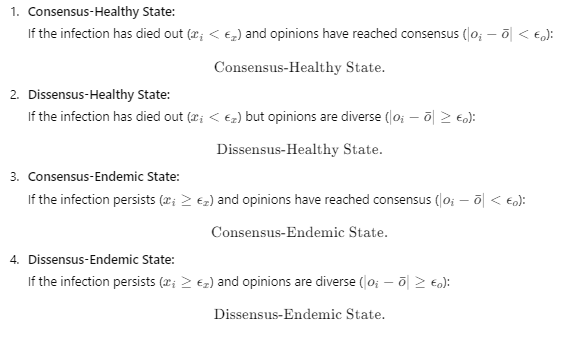

## Plots

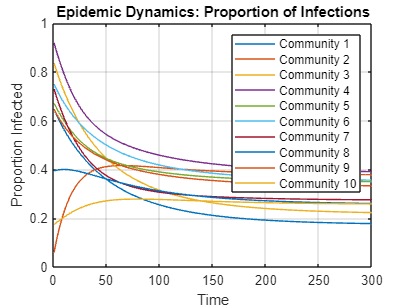

% Plot 1: Epidemic Dynamics
figure(1);
plot(1:t_max, x_history');
title('Epidemic Dynamics: Proportion of Infections');
xlabel('Time');
ylabel('Proportion Infected');
legend(arrayfun(@(i) sprintf('Community %d', i), 1:n, 'UniformOutput', false));
grid on;

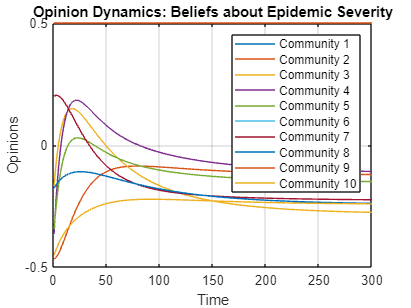


% Plot 2: Opinion Dynamics
figure(2);
plot(1:t_max, o_history');
title('Opinion Dynamics: Beliefs about Epidemic Severity');
xlabel('Time');
ylabel('Opinions');
legend(arrayfun(@(i) sprintf('Community %d', i), 1:n, 'UniformOutput', false));
grid on;

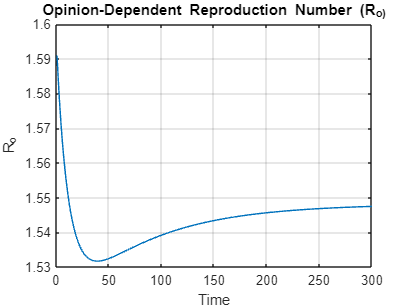


% Plot 3: Opinion-Dependent Reproduction Number (R_o)
figure(3);
plot(1:t_max, R_o_history);
title('Opinion-Dependent Reproduction Number (R_o)');
xlabel('Time');
ylabel('R_o');
grid on;